# Particle Discovery Lab

### SETUP

Download the MATLAB workspace for this exercise. Go to the Home menu, Environment section and select "Set Path" -- choose the location of your workspace file. Then run:

load('fourlep_20112012.mat')

## DAY 1 = RECONSTRUCTION

Use energy and momentum conservation to reconstruct a decay of particle X -> mu + mu

% Choose how many events to process
Ntoprocess = input('How many events to process? ');

% Initialize a vector that will hold 1 invariant mass per event
Masses = [];
KineticEnergy = [];

% User-chosen min/max values and resolution
Min = input('Type in your min (in GeV): ');
Max = input('Type in your max (in GeV): ');
n = input('Type in the number of bins: ');
BinWidth = (Max - Min)/n;

% Loop over the number of events with at least 2 muons
disp(['Looping over ' num2str(Ntoprocess) ' events...']);

Looping over 278 events...


for i = 1:Ntoprocess

    % COMPUTE the mass of particle X -> mu mu
    % SOLUTION: E = E1 + E2, p = p1 + p2 vector sum
    %           mc2 = sqrt( E^2 - p^2 )
    Esum = E(i,1) + E(i,2) + E(i,3) + E(i,4);
    Px = px(i,1) + px(i,2) + px(i,3) + px(i,4);
    Py = py(i,1) + py(i,2) + py(i,3) + py(i,4);
    Pz = pz(i,1) + pz(i,2) + pz(i,3) + pz(i,4);
    M = sqrt( Esum^2 - Px^2 - Py^2 - Pz^2 );

    % THINK: Is this mass in your window from Min to Max? 
    %        What should you do if it's outside the window?
    % SOLUTION: discard those events

    if(M > Min && M < Max)
        
        % Calculate the Kinetic Energy of particle X. 
        % Store KE and mass values to plot later  
        % Tip: make sure you mass value if "real" by using real(massvalue)
        Masses = [Masses M];  
        KineticEnergy = [KineticEnergy Esum - real(M)]; 
        % they'll try to solve for v! Redirect to Etotal - Erest = K
    end

end

## HISTOGRAMMING -- create mass and KE histograms

THINK: 

- What do you expect your kinetic energy histogram to look like? 

- What do you expect your mass histogram to look like? 

*SOLUTION: higher energies are always less probable, so falling from 0. Mass is similar: falling from low -> high, but with a bump*

**Draw a **`histogram` of counts versus mass. Tool:

- `histogram: `needs the Mass values list and a number of bins 

- Tip: store the histogram object itself! `h = histogram(...inputs...)`

Draw a `histogram` of counts versus mass. The `histogram` function needs: Mass values list, Mass "bin edges" list 

figure(1)
h = histogram(real(Masses),n,'DisplayStyle','stairs');
xlabel('Mass [GeV]');
ylabel('Number of muon pairs');
hold on; % this lets you draw on top of this plot later
axis manual; % this keeps the axes fixed to where they are now


THINK: 

- What should the error bars be for each bin? 

- What should you do if the bin has zero entries?

*SOLUTION: Error on N = sqrt(N)*

*           Zero is not exact! Just lack of data. Use error_up = 1 (or dig deeper and talk about Poisson upper bound on 0!).*

*           But error bars shouldn't dip below 0 here, that would be unphysical.*

Tools: 

- `h`: this object has "properties" that include a list of all the bin edges and a list of all the y-axis values from your histogram

- `errorbar`: draws dots+bars, needs the bin centers list, y values list, down uncert list, up uncert list 

% Get lists of bin edges and y-axis values from the histogram
counts = h.Values;
MassEdges = h.BinEdges;
disp(['Peak bin content: ' num2str(max(counts))]); % just to check

Peak bin content: 11


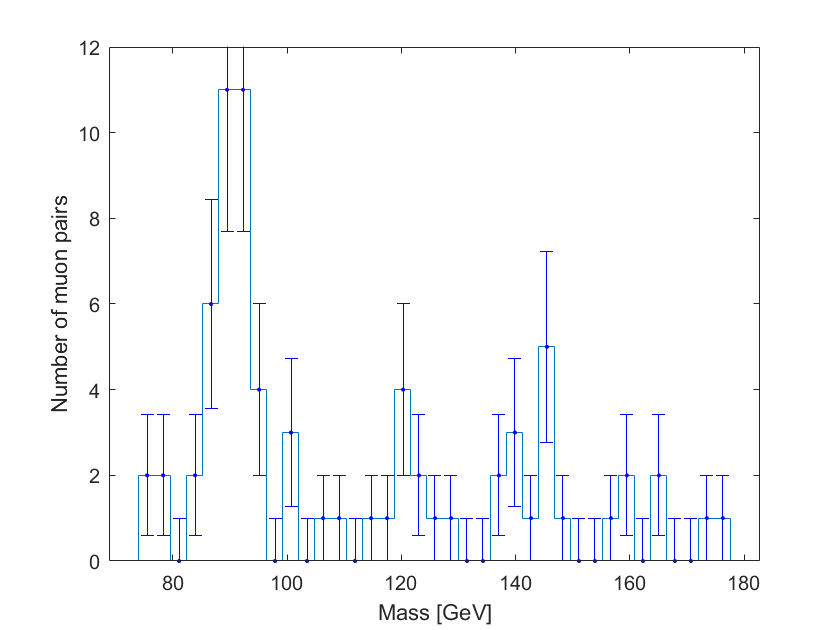

% Make an errorbar plot for counts versus mass
MassCenters = MassEdges(1:end-1)+BinWidth/2;

error_up = max(sqrt(counts),1); % avoid error of 0 going up
error_down = sqrt(counts);      % but error going down can be 0
errorbar(MassCenters,counts,error_down,error_up,'b.'); % b. = blue dots
hold off;

Draw another `histogram` of counts vs kinetic energy. Add error bars.

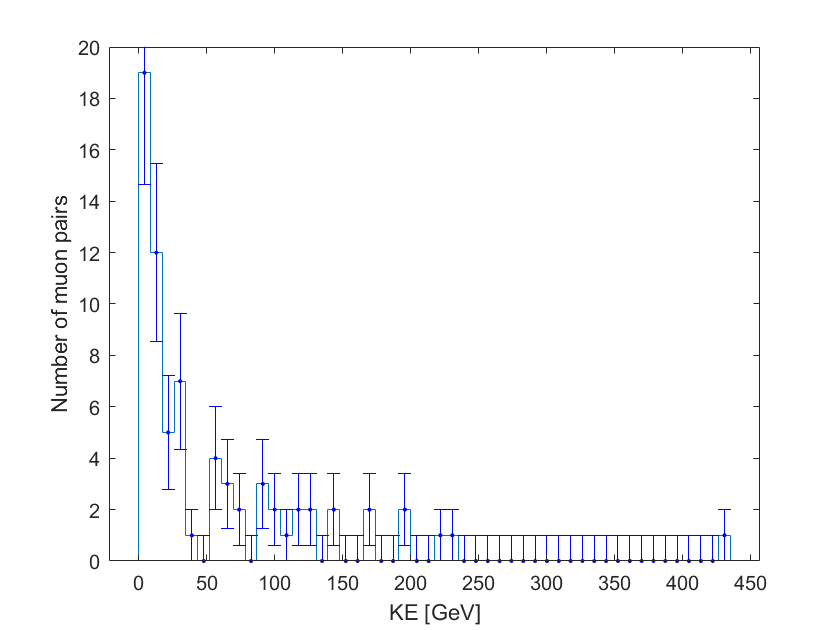

figure(2)
h2 = histogram(KineticEnergy,50,'DisplayStyle','stairs'); 
%set(gca,'YScale','log'); %log scale on the y axis
xlabel('KE [GeV]'); 
ylabel('Number of muon pairs');
hold on; % this lets you draw on top of this plot later
axis manual; % this keeps the axes fixed to where they are now

KEcounts = h2.Values;
KEedges = h2.BinEdges;
KEwidth = h2.BinWidth;  % new!
KEcenters = KEedges(1:end-1)+KEwidth/2;
KEerror_up = max(sqrt(KEcounts),1); % avoid error of 0 going up
KEerror_down = sqrt(KEcounts);      % but error going down can be 0
errorbar(KEcenters,KEcounts,KEerror_down,KEerror_up,'b.'); % b. = blue dots
%set(gca,'YScale','linear'); %back to linear scale on the y axis
%ylim([0,10]) % to see if errors up from count of 0 are correct
hold off;

## Great work! 

- **SAVE** these plots to represent your raw data in your report.

- **SAVE** a DAY1 workspace to start from next time (Click in the workspace area, then CTRL-S)

## DAY 2 = FITTING -- fit background on either side of the peak

LOAD your DAY1 workspace

Vocab: imagine a mass plot with a bump in the middle

- "Peak window": region along x-axis under the peak

- "background": smoothly falling slope of random events, including some of the events in the peak window

- "signal": events in the peak window minus the background

CHOOSE mass values or bin numbers for where the peak lies. 

peakmin = input('Type in your peak min boundary (in GeV): ');
peakmax = input('Type in your peak max boundary (in GeV): ');
iMin = round((peakmin-Min)/BinWidth,0)
iMax = round((peakmax-Min)/BinWidth,0) + 1

REMOVE the peak window completely from your list of: 

- mass bin centers

- mass counts

- mass uncertainties

This forms your BACKGROUND dataset

bkgcounts = [counts(2:iMin) counts(iMax:length(counts))];
bkgcenters = [MassCenters(2:iMin) MassCenters(iMax:length(MassCenters))];
bkgerror_up = [error_up(2:iMin) error_up(iMax:length(error_up))];
bkgerror_down = [error_down(2:iMin) error_down(iMax:length(error_down))];

**PERFORM a polynominal fit to the background**

    THINK: Which type of curve do you expect will match your data best? Imagine a curve connecting the two sides under your peak.

*    SOLUTION: Probably a line, or 2rd/3rd order poly. The group with range 30-150 will need to crank up the order to maybe 5-6.*

    Tool: 

- `pollsf` gives fit parameters, parameter uncertainties, fitted y-values, and a chi^2 value. It needs a bin center list, count list, count uncertainty list, and number of parameters.

- Tip: look up how to store multiple output variables when you call a function

numpars = input('How many params in your polynominal? 1 (flat), 2 (line), etc: ');
[params,paramerrs,fityvals,chisq] = pollsf(bkgcenters,bkgcounts,bkgerror_up,numpars);

EVALUATE your fit by chi^2 and plotting

- Plotting: does the shape make any sense? 

- Chi^2 is defined in Eq. 29. It describes the difference between the points and the fitted curve. LARGER chi^2 tends to mean more difference or scatter of points.

- OPTIMALLY, Chi^2 / (# points - # parameters) is around 1

REPEAT fitting until you are satisfied with both of these metrics

disp(['Chi2/dof = ' num2str(chisq/(length(bkgcenters)-numpars))])
disp(params)

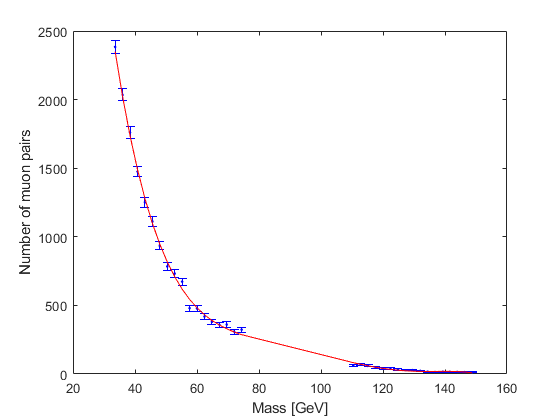

%params = fliplr(params'); %noted here for later when we want more x values
% %fittedbkgcounts = polyval(params,bkgcenters);

figure(3)
errorbar(bkgcenters,bkgcounts,bkgerror_down,bkgerror_up,'b.');
xlabel('Mass [GeV]');
ylabel('Number of muon pairs');
hold on;
plot(bkgcenters,fityvals,'r-')
hold off;

## SUBTRACTION -- now you will subtract that background from data

THINK: 

- How will you estimate background in the signal peak window?

- What do you expect the curve to look like after background subtraction?

*SOLUTION: evaluate the function at x-values inside the peak window After subtraction should look like a ~Gaussian peak*

params = fliplr(params')  % polyval wants a row from high -> low order

params = 	1.0e+04 *

   -0.0000    0.0000   -0.0000    0.0014   -0.0705    1.4906


fittedcounts = polyval(params,MassCenters) % more x-axis bins than before

fittedcounts = 	1.0e+03 *

    2.7278    2.3507    2.0221    1.7370    1.4910    1.2798    1.0995    0.9464    0.8173    0.7091    0.6188    0.5441    0.4825    0.4320    0.3907    0.3568    0.3291    0.3060    0.2866    0.2699    0.2551    0.2415    0.2286    0.2161    0.2035    0.1907    0.1777    0.1643    0.1506    0.1368    0.1229    0.1091    0.0957    0.0828    0.0707    0.0595    0.0495    0.0407    0.0335    0.0277    0.0234    0.0205    0.0189    0.0184    0.0185    0.0189    0.0189    0.0177    0.0146    0.0085


PLOT the background curve on top of your mass histogram (save it!)

THINK: Are your estimated bkg values at all uncertain?

*SOLUTION: Yes, of course! But we have not discussed covariance and will make the ~safe assumption that our background uncert is small. The pollsf function chooses to return only variances, but you could edit it to return the whole matrix!*

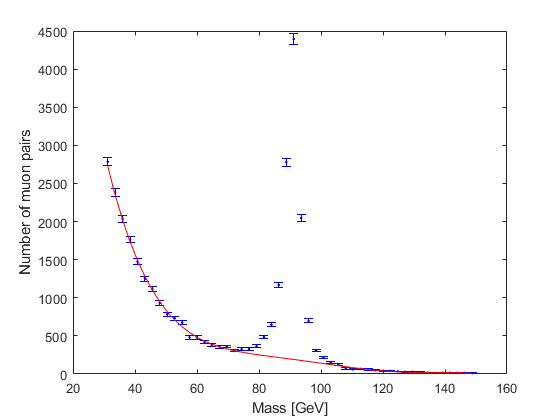

figure(4)
errorbar(MassCenters,counts,error_down,error_up,'b.');
xlabel('Mass [GeV]');
ylabel('Number of muon pairs');
hold on;
plot(MassCenters,fittedcounts,'r-')
hold off;

EVALUATE signal = data - background

THINK: 

- Do you have any bins where the background estimate is larger than the data? What do you think about this situation? 

- How could you find the uncertainty in data - background?

*SOLUTION: Values < 0 can happen when subtracting background, it's no longer necessarily unphysical. Uncertainty is like radioactivity: err = sqrt(errData^2 + errBkg^2), NOT sqrt after subtracting! You could estimate errBkg = 0, or assume Poisson and say errBkg = sqrt(N)*

sigcount = counts-fittedcounts;

sigerror_up = max(sqrt(counts+fittedcounts),1); % again, up error not 0
sigerror_down = sqrt(counts+fittedcounts);

PLOT the signal-only peak with ERROR BARS

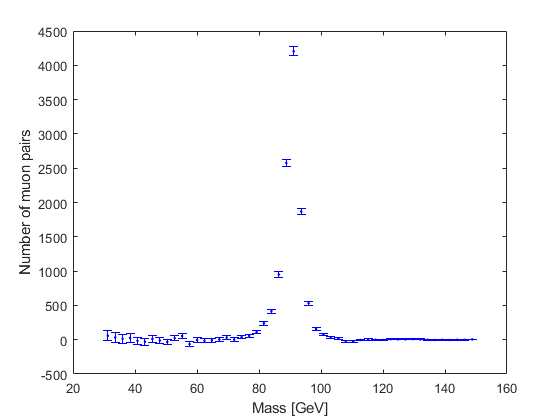

figure(5)
errorbar(MassCenters,sigcount,sigerror_up,sigerror_down,'b.'); 
xlabel('Mass [GeV]');
ylabel('Number of muon pairs');

## Great work! 

- **SAVE** the data+background and signal-only plots as analysis in your report.

- **SAVE** a DAY2 workspace!

## DAY 3 = CHARACTERIZATION of your signal

LOAD your DAY2 workspace

EXTRACT the characteristics of your signal peak

THINK: Which statistical distribution describes your signal peak?

*SOLUTION: they should do well with a Gaussian shape, which I've provided in gausfit.m.*

**TOOL nlinfit: fits a given nonlinear function to data **

- outputs: [paramsGaus, R, J, covariance]. We don't care about R or J, but want "params" (the fitted function parameters) and "covariance" (uncertainty squared for each parameter runs down the diagonal).

- inputs: nlinfit(x-axis data, y-axis data, function handle, initial parameter guess)

- usage example: [paramsGaus, R, J, covariance] = nlinfit(X, Y, @functionName, guess)

Look at your signal peak to create a vector of initial guesses for Gaussian parameters. 

THINK: what do the parameters represent?

*SOLUTION: guess should look like guess = [peak y-axis value, mean, width]. I've used an if statement to make guesses for each case here. The Upsilon group can fit their tallest peak well by providing that guess. For the smaller peaks they should update their guess and restrict the data range that they pass to the fitter. *

% Create an initial guess vector
if Min < 4
    guess = [1000,3.1,0.1];
elseif Min < 20
    guess = [500,9.5,0.1]; % first/tallest peak
else
    guess = [1000,90,5];
end

Call **nlinfit** on your signal peak using the function **gausfit.** 

[paramsGaus,R,J,covariance] = nlinfit(MassCenters,sigcount,@gausfit,guess); 

% UPSILON 2nd peak: guess 10.0 and pass MassCenters(19:22), sigcount(19,22)
% UPSILON 3rd peak: guess 10.5 and pass MassCenters(23:27), sigcount(23,27)
% I used 40 bins total for this solution

EXTRACT the **mean** and **width** of your fitted curve.

*SOLUTION: they need to access specific elements of ****paramsGaus**** and ****covariance****. The 2nd element is the mean and the 3rd element is the width.*

mu = paramsGaus(2);                     % order is N, mu, sigma
mu_uncert = sqrt(covariance(2,2));      % picking the diagonal element gives uncert^2          
sigma = paramsGaus(3);                      
sigma_uncert = sqrt(covariance(3,3)); 

disp(['Gaussian mean = ' num2str(mu) ' +/- ' num2str(mu_uncert)]);
disp(['Gaussian width = ' num2str(sigma) ' +/- ' num2str(sigma_uncert)]);

PLOT the Gaussian fit on top of your signal peak as a final figure. Include a legend. 

gaus_x = Min:(Max-Min)/100:Max;
gaus_y = gausfit(paramsGaus,gaus_x);

figure(6)
errorbar(MassCenters,sigcount,sigerror_up,sigerror_down,'b.'); 
xlabel('Mass [GeV]');
ylabel('Number of muon pairs');
hold on
plot(gaus_x,gaus_y,'k')
legend('data','Gaussian fit','Location','best')

COMPARE the number of signal events in signal peak window to the number of background events under the peak window.

THINK: 

- how can you find the number of events in the signal peak? 

- How can you find the number of bkg events under the peak?

PRINT these values along with their uncertainties

*SOLUTION: NSignal = sum up counts from "sig counts". NBackground = sum up counts from "fittedcounts". Of course, the students are free to integrate their 2 fitted functions from peakmin to peakmax, but this is difficult to program. For uncertainties, they should be able to prove that sqrt(SummedTotalN) is really what you get from propagation of sqrt(N) errors through the sum.*

bkginpeak = fittedcounts(iMin:iMax-1);
peakcounts = counts(iMin:iMax-1);
siginpeak = sigcount(iMin:iMax-1);

disp(['Number of background events in peak = ' num2str(sum(bkginpeak))...
     ' +/- ' num2str(sqrt(sum(bkginpeak)))]);
disp(['Number of signal events in peak = ' num2str(sum(siginpeak))...
     ' +/- ' num2str(sqrt(sum(peakcounts+bkginpeak)))]);

### Almost done!

THINK:

- Can you statistically distinguish signal from background?

- Can you find this particle with a web search for you mass?

- Research this particle (pdg.lbl.gov), find its width (capital Gamma)

- Do your mass & width agree with the known values within their uncertainties? Find percent differences and also discrepancy/significance.

- If your width is *much* larger than accepted, why might this be?

*SOLUTION: Generally their masses should agree within the observed widths, and usually within a few times the parameter uncertainty. For Z bosons (short-lived) the width should also agree because it is large (several GeV). For the mesons their width will be MUCH too large -- the CMS detector resolution is not fine enough to measure the lifetime of these particles and the width is inflated. *